# **ACM 11 Probability Primer (Spring 2021)**

**This is not an exercise to turn in. This is just provided as a demo of how to work with a few different random variables in MATLAB.**

This live script introduces four different random variables: binomial, random integers in a fixed interval, uniform continuous random variables, and normal random variables. The purpose is to show the analytical probability mass function/probability density function, and to demonstrate how to use MATLAB to sample from the random variables.

We start with two models of discrete random variables:

** Model 1 (Tossing a coin)**

Consider a biased coin such that when it's flipped, the probability that a head appears is $p$ while the probability that a tail appears is $1-p$, where $p\in \left(0,1\right)\;$is some fixed parameter (In particular, when $p=0\ldotp 5$, the coin is called unbiased). Mathemtically, we use $1\;$to denote a head and $0$ to denote a tail. Take a fixed $n\in Z^+$ and consider tossing the coin $n$ times. Let $X$ denote the number of trials that a head appears.  Then we have that $X\in \left\lbrace 0,1,\cdots ,n\right\rbrace$ is a discrete random variable, whose distribution is given below:


$$\mathbb{P}[X=k] = {n \choose k}p^{k}(1-p)^{n-k} \ (0 \leq k \leq n)$$


Such a discrete distribution is called the Binomial distribution, which can be abbreviated as $\mathrm{Bino}\left(n,p\right)$.

**(1.1) **Let's firstly plot the probability mass function (PMF) of $\mathrm{Bino}\left(n,p\right)$. Feel free to modify the value of $n$ and $p$ to see how the plot of the PMF changes as $p\;$changes.

One helpful built-in functions is binopdf, whose page is given below:

[https://www.mathworks.com/help/stats/binopdf.html](https://www.mathworks.com/help/stats/binopdf.html)

n1 = 10     % number of coin tosses (can change to any positive integer)

n1 = 10

p1 = 0.5    % probability of heads (can change to any value in (0,1))

p1 = 0.5000

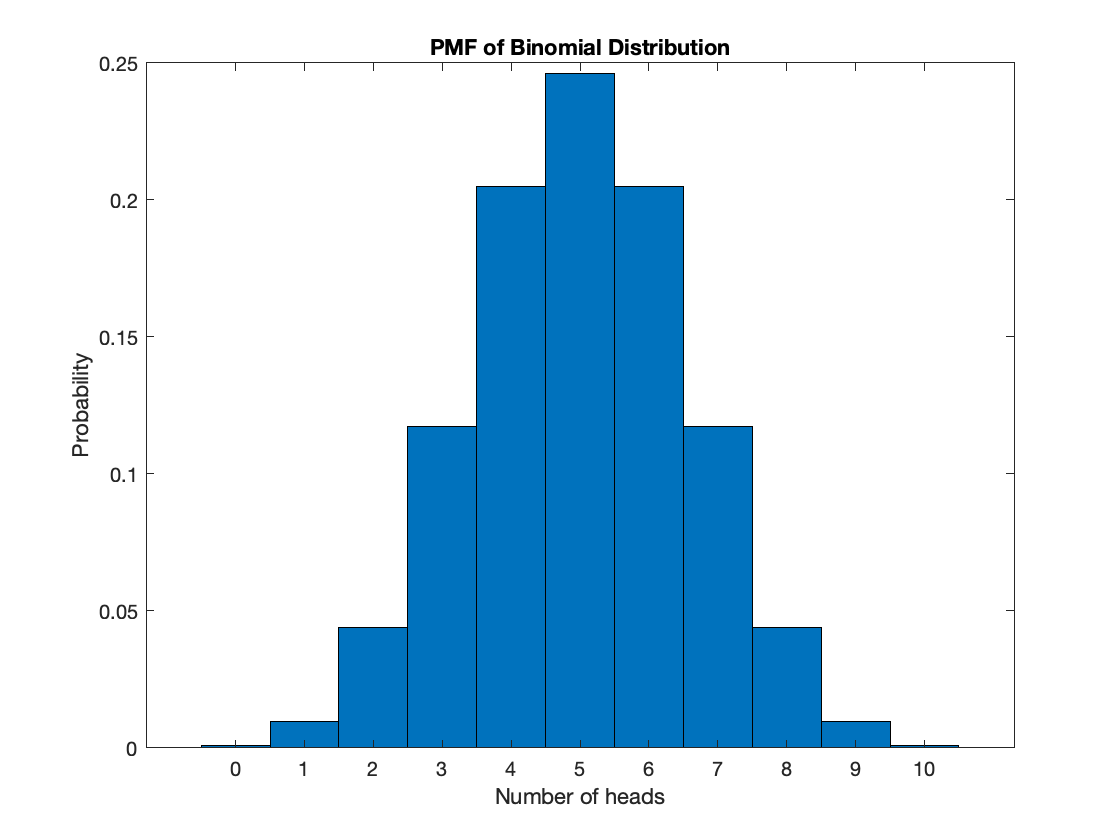


% Calculate the probability mass function (PMF) analytically
x1 = 0:n1;
y1 = binopdf(x1,n1,p1);

% Plot the PMF
figure(1);
bar(x1,y1,1);

% Label the axes and title
xlabel('Number of heads')
ylabel('Probability')
title('PMF of Binomial Distribution')

**(1.2) **Let's use MATLAB to simulate the coin tossing process. The idea is to generate $N$ i.i.d samples from $\mathrm{Bino}\left(n,p\right)$, where $N$ denotes the number of realizations. Then we can visualize the simulation by plotting the histogram of the $N$ samples. Feel free to modify the value of $N$ to see how the histogram plot changes as $N\;$varies.

Two helpful built-in functions are binornd and histogram, whose tutorial pages are given below:

[https://www.mathworks.com/help/stats/binornd.html.](https://www.mathworks.com/help/stats/binornd.html.)

[https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.histogram.html](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.histogram.html)

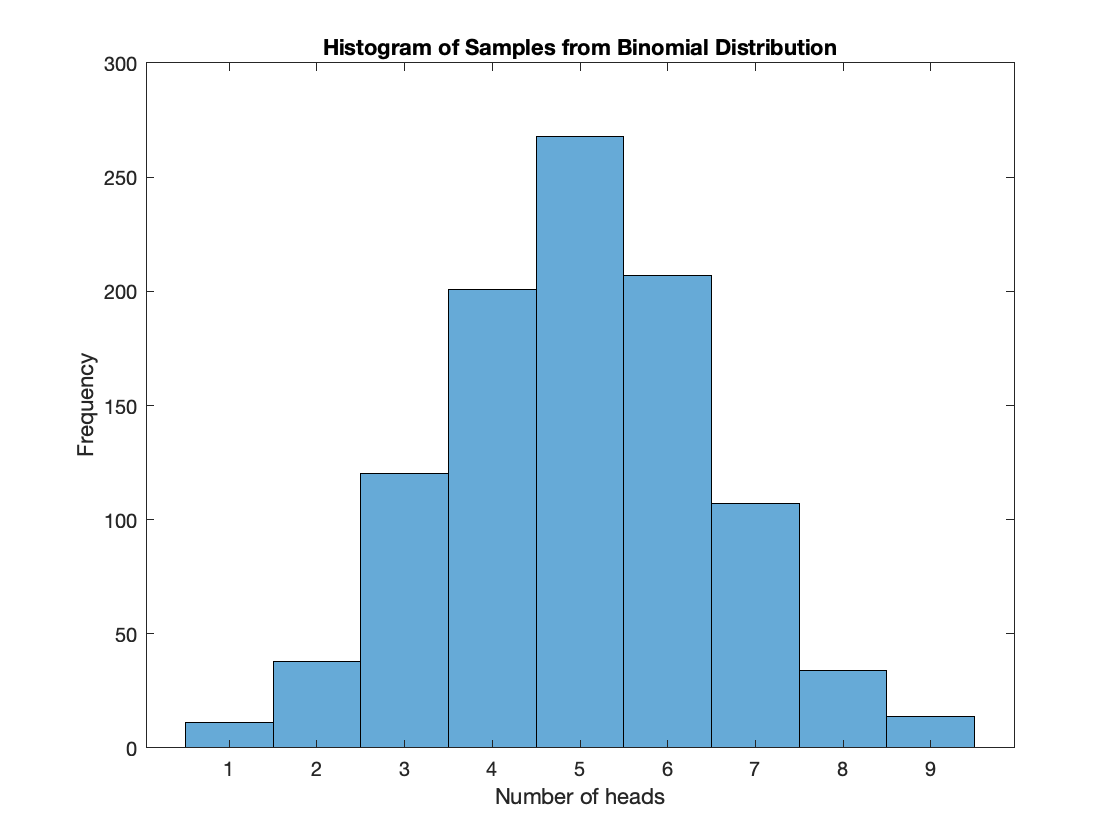

N1 = 1000;              % Feel free to change the number of experiments
sample1 = binornd(n1,p1,1,N1);   % generates 1xN1 vector of samples from Bino(n1,p1)

% Plot the Histogram (empirical PMF)
figure(2);
histogram(sample1);
xlabel('Number of heads');
ylabel('Frequency');
title('Histogram of Samples from Binomial Distribution');

**(1.3) **Let's consider the mean value of the distribution $\mathrm{Bernoulli}\left(p\right)$. On the one hand, the theoretical value of the mean can be calculated as follows:


$$\mathbb{E}[X] = \sum_{k=0}^{n}k{n \choose k}p^{k}(1-p)^{n-k} = np$$


On the other hand, the practical estimate of the mean is given by the average of the values in the generated sample.

Based on the simulation, let's compute the theoretical value and the practical estimate of the mean. We will compare these two values by computing their absolute difference. Please take different values of $N$ and observe how the absolute difference changes as $N$ varies.

mean_theo1 = n1*p1;
mean_prac1 = mean(sample1);
diff1 = abs(mean_theo1 - mean_prac1);
fprintf(['Difference between sample mean and theoretical mean: ',num2str(diff1),'\n'])

Difference between sample mean and theoretical mean: 0.02


**Model 2 (Six-sided dice)**

Consider a unbiased six-sided dice. Equivalently speaking, for any integer $i\in \left\lbrace 1,2,3,4,5,6\right\rbrace ,$ the probability that we get $i$ when we roll the dice once is equal to $\frac{1}{6}\ldotp \;$ Mathemtically, if we let $X$ denote the outcome of the dice when it's rolled once. Then we have that $X\in \left\lbrace 1,2,3,4,5,6\right\rbrace$ is a discrete (uniform) random variable, whose distribution is given below:


$$\mathbb{P}[X=k] = \frac{1}{6} \ (1 \leq k \leq 6)$$


Such a discrete distribution is called a discrete uniform distribution, which can be abbreviated as $\mathrm{unif}\left\lbrace 1,6\right\rbrace$.

**(2.1) **Let's firstly plot the probability mass function (PMF) of $\mathrm{unif}\left\lbrace 1,6\right\rbrace$. 

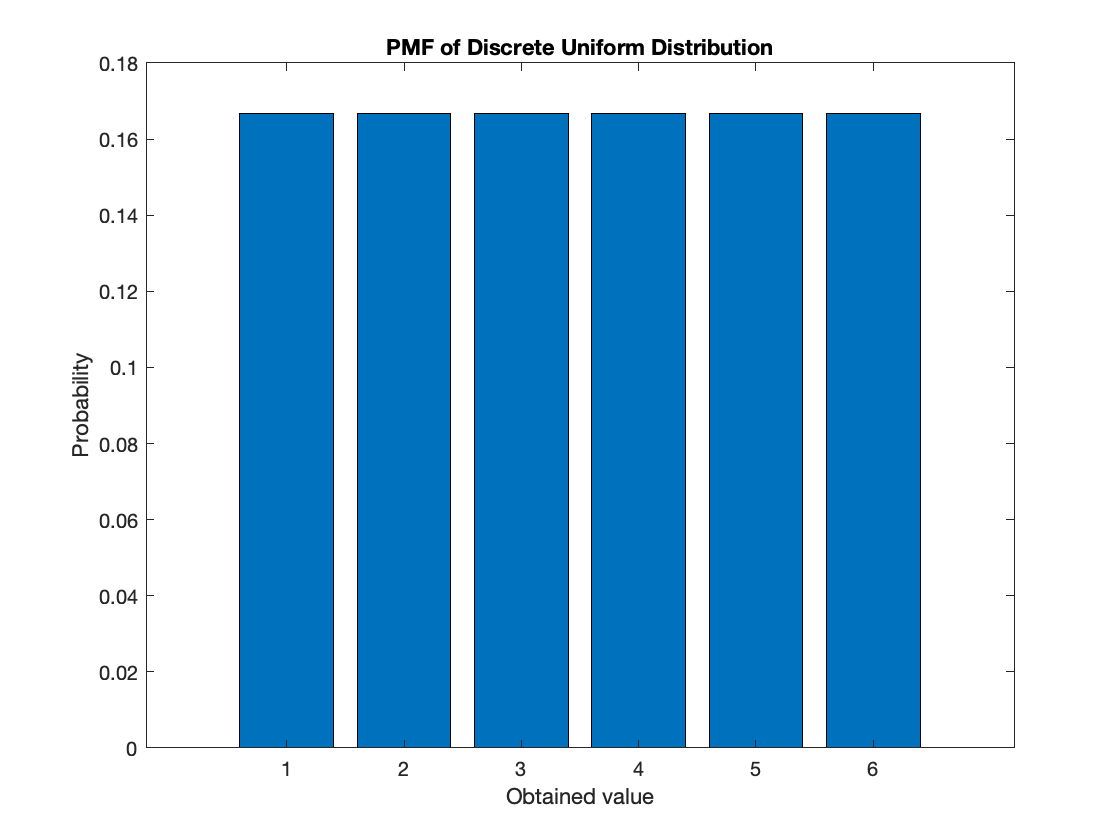

% Define the PMF
value2 = [1 2 3 4 5 6]; 
proba2 = [1/6 1/6 1/6 1/6 1/6 1/6];

% Plot the PMF
figure(3);
bar(value2,proba2)
xlabel('Obtained value')
ylabel('Probability')
title('PMF of Discrete Uniform Distribution')

**(2.2) **Let's use MATLAB to simulate the dice rolling process. The idea is to generate $N$ i.i.d samples from $\mathrm{unif}\left\lbrace 1,6\right\rbrace$, where $N$ denotes the number of realizations. Then we can visualize the simulation by plotting the histogram of the $N$ samples. Feel free to modify the value of $N$ to see how the histogram plot changes as $N\;$varies.

One helpful built-in functions is randi, whose tutorial pages are given below:

[https://www.mathworks.com/help/matlab/ref/randi.html](https://www.mathworks.com/help/matlab/ref/randi.html)

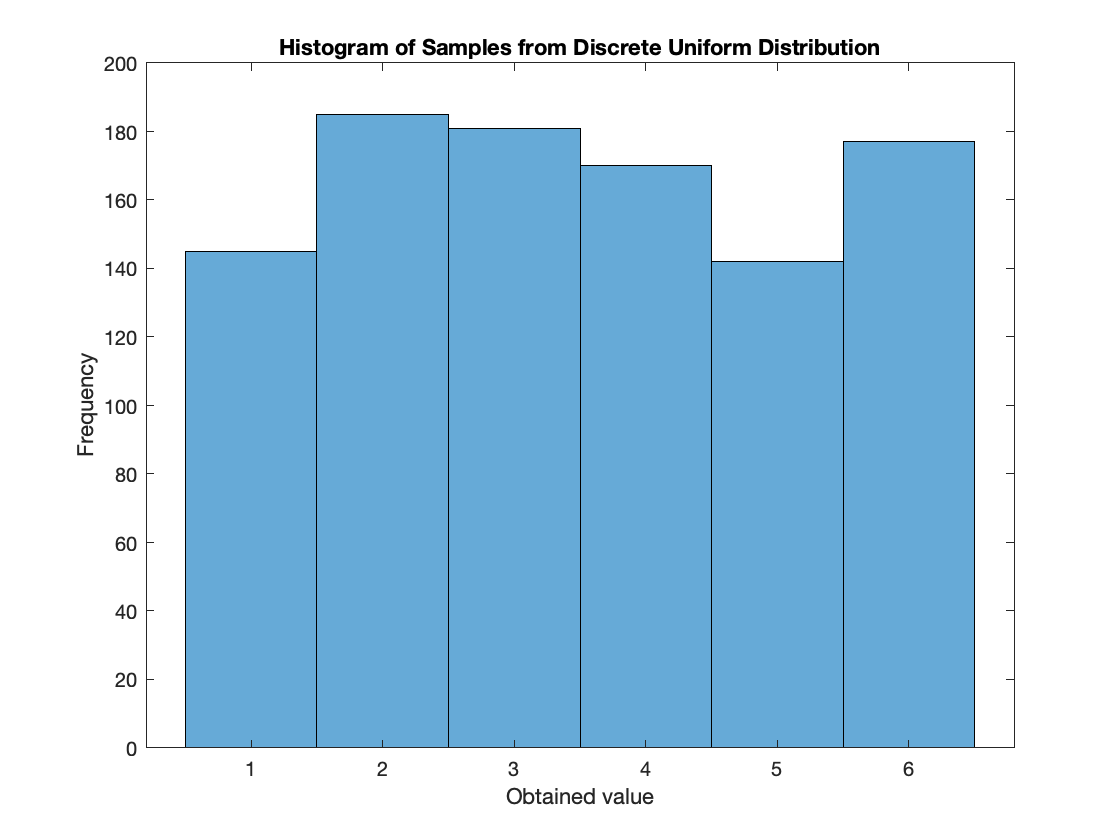

N2 = 1000;          % # of experiments (die rolls)
sample2 = randi(6,1,N2);

% Plot the Histogram
figure(4);
histogram(sample2);
xlabel('Obtained value');
ylabel('Frequency');
title('Histogram of Samples from Discrete Uniform Distribution');

**(2.3) **Let's consider the mean value of the distribution $\mathrm{unif}\left\lbrace 1,6\right\rbrace$. On the one hand, the theoretical value of the mean can be calculated as follows:


$$\mathbb{E}[X] = \frac{1}{6}(1+2+3+4+5+6)= 3.5$$


On the other hand, the practical estimate of the mean is given by the average of the values in the generated sample.

Based on the simulation, let's compute the theoretical value and the practical estimate of the mean. We will compare these two values by computing their absolute difference. Please take different values of $N$ and observe how the absolute difference changes as $N$ varies.

mean_theo2 = 3.5;
mean_prac2 = mean(sample2);
diff2 = abs(mean_theo2 - mean_prac2);
fprintf(['Difference between sample mean and theoretical mean: ',num2str(diff2),'\n'])

Difference between sample mean and theoretical mean: 0.01


After examining the two discrete models, let's now proceed to consider two continuous models.

**Model 3 (Uniform continuous distribution)**

Let's consider a continuous random variable whose distribution is given by:


$$f(x) = \begin{cases} 
\frac{1}{\theta} \ (x \in [0, \theta])\\
0 \ (\text{otherwise})
\end{cases}$$


Such a discrete distribution is called a continuous uniform distribution, which can be abbreviated as $\mathrm{unif}\left\lbrack 0,\theta \right\rbrack$.

**(3.1) **Let's firstly plot the probability density function (PDF) $f\left(x\right)$ of $\mathrm{unif}\left\lbrack 0,\theta \right\rbrack$. Feel free to modify the value of $\theta$ to see how the plot of the PDF changes as $\theta \;$changes.

Two helpful built-in functions are makedist and pdf, whose tutorial pages are given below:

[https://www.mathworks.com/help/stats/makedist.html](https://www.mathworks.com/help/stats/makedist.html)

[https://www.mathworks.com/help/stats/prob.normaldistribution.pdf.html](https://www.mathworks.com/help/stats/prob.normaldistribution.pdf.html)

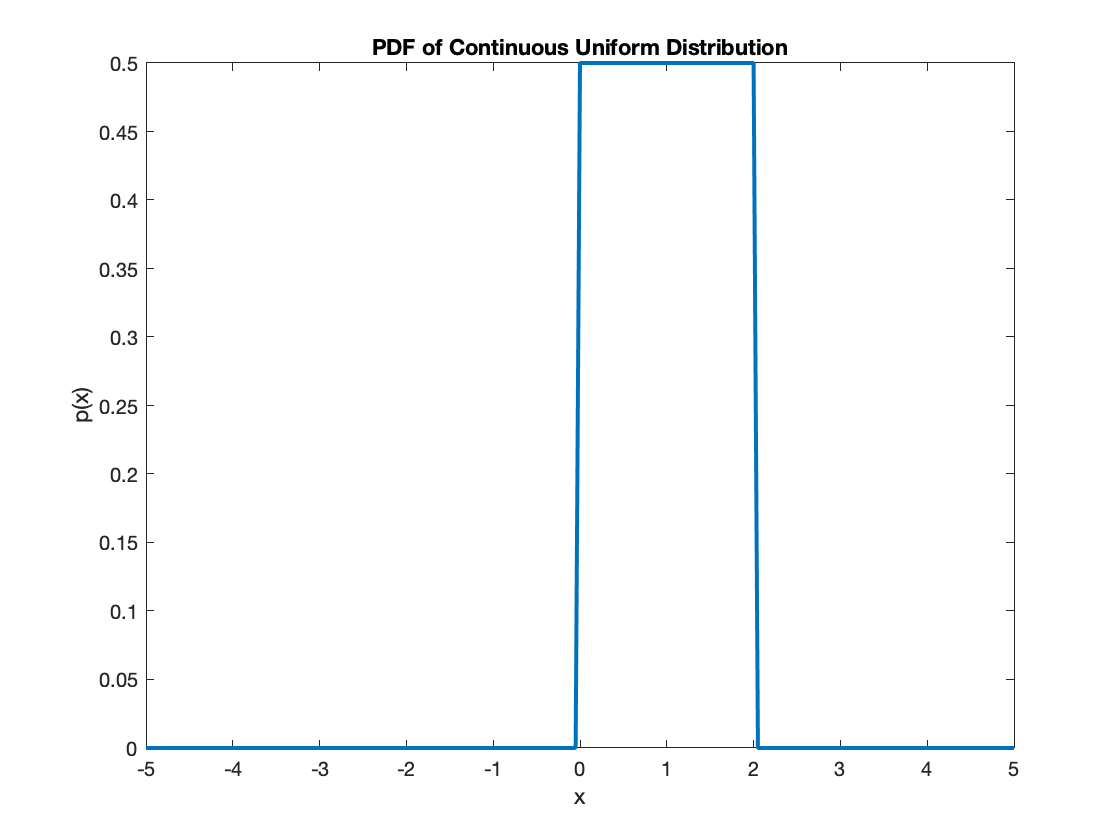

theta3 = 2;     % Feel free to change the parameter theta
x3 = -5:0.05:5; % x-values for plotting

pd3 = makedist('Uniform','lower',0,'upper',theta3);
pdf3 = pdf(pd3,x3); % Define the uniform continuous distribution

% Plot the PDF
figure(5);
plot(x3,pdf3);
xlabel('x')
ylabel('p(x)')
title('PDF of Continuous Uniform Distribution')

**(3.2) **Let's use MATLAB to sample from the distribution. The idea is to generate $N$ i.i.d samples from $\mathrm{unif}\left\lbrack 0,\theta \right\rbrack$, where $N$ denotes the number of realizations. Then we can visualize the sampling by plotting the histogram of the $N$ samples. Feel free to modify the value of $N$ to see how the histogram plot changes as $N\;$varies.

One helpful built-in functions is rand, whose tutorial pages is given below:

[https://www.mathworks.com/help/matlab/ref/rand.html](https://www.mathworks.com/help/matlab/ref/rand.html)

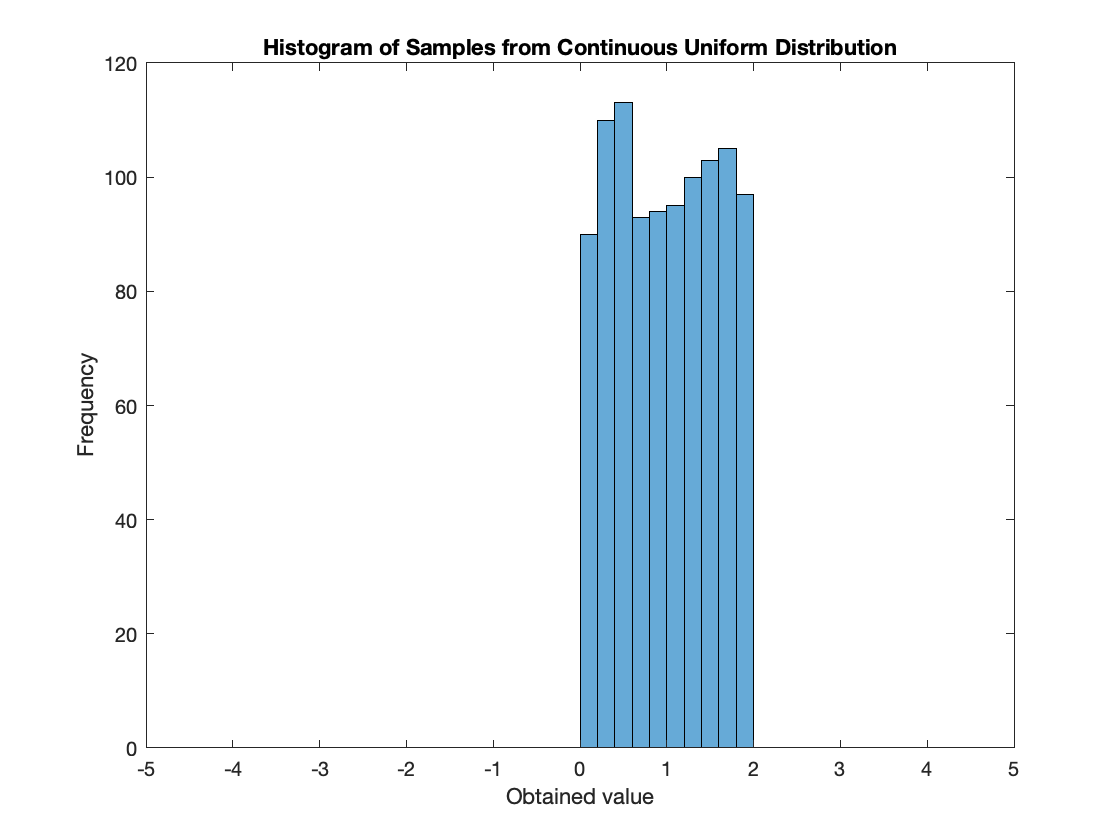

N3 = 1000;              % number of realizations
sample3 = theta3.*rand(N3,1);    % Note that here we need to transform [0,1] to [0,\theta]

% Plot the Histogram
figure(6);
histogram(sample3);
xlabel('Obtained value');
ylabel('Frequency');
xlim([-5 5])
title('Histogram of Samples from Continuous Uniform Distribution');

**(3.3) **Let's consider the mean value of the distribution $\mathrm{unif}\left\lbrack 0,\theta \right\rbrack$. On the one hand, the theoretical value of the mean can be calculated as follows:


$$\mathbb{E}[X] = \int_{0}^{\theta}xf(x)dx= \frac{1}{2}\theta$$


On the other hand, the practical estimate of the mean is given by the average of the values in the generated sample.

Based on the simulation, let's compute the theoretical value and the practical estimate of the mean. We will compare these two values by computing their absolute difference. Please take different values of $N$ and observe how the absolute difference changes as $N$ varies.

mean_theo3 = theta3./2;
mean_prac3 = mean(sample3);
diff3 = abs(mean_theo3 - mean_prac3);
fprintf(['Difference between sample mean and theoretical mean: ',num2str(diff3),'\n'])

Difference between sample mean and theoretical mean: 4.247e-06


**Model 4 (Normal distributions)**

Let's consider a continuous random variable whose distribution is given by:


$$f(x) = \frac{1}{\sqrt{2\pi}\sigma}e^{-\frac{1}{2}(\frac{x-\mu}{\sigma})^2}$$


Such a discrete distribution is called a normal distribution, which can be abbreviated as $\mathcal{N}(\mu,\sigma^2)$.

**(4.1) **Let's firstly plot the probability density function (PDF) $f\left(x\right)$ of $\mathcal{N}(\mu,\sigma^2)$. Feel free to modify the value of $\mu$ and $\sigma^2$ to see how the plot of the PDF changes as the parameters change.

One helpful built-in functions is normcdf, whose tutorial pages is given below:

[https://www.mathworks.com/help/stats/normpdf.html](https://www.mathworks.com/help/stats/normpdf.html)

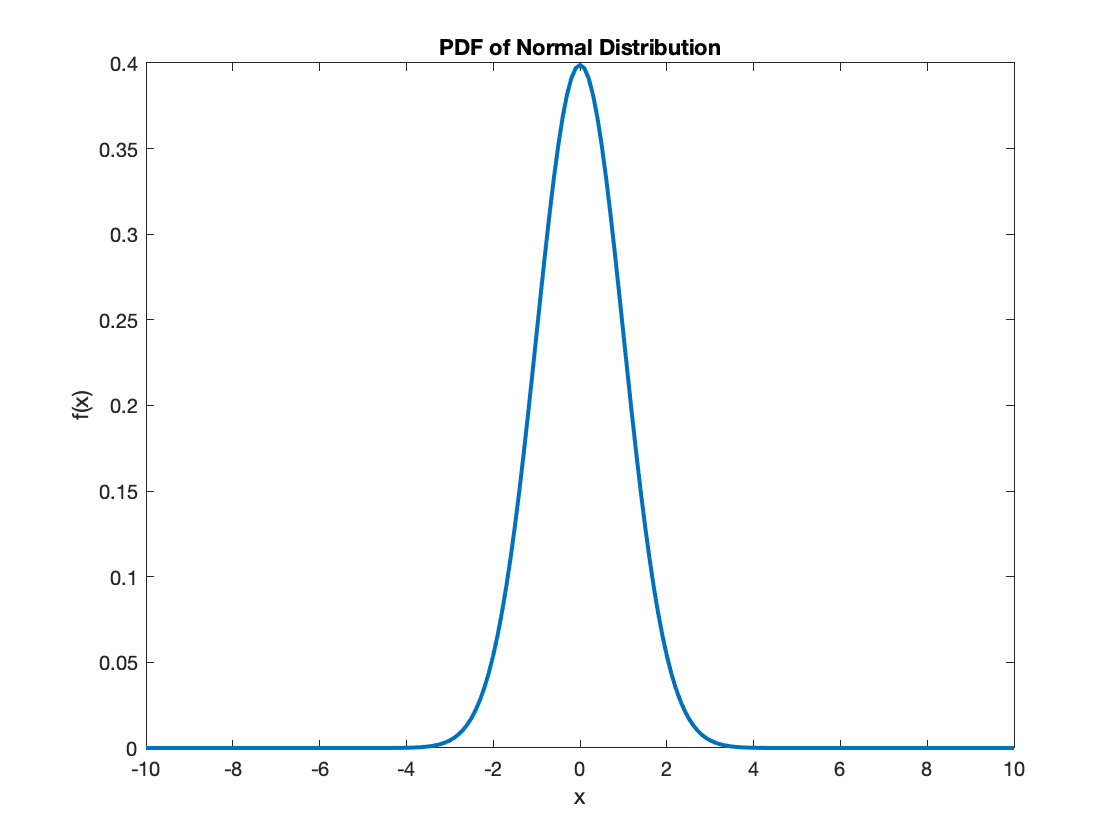

mu4 = 0; sigma4 = 1;    % can change these values 

x4 = -10:1e-1:10;       % x-values to plot at
y4 = normpdf(x4, mu4, sigma4);

% Plot the PDF
figure(7);
plot(x4,y4);
xlabel('x')
ylabel('f(x)')
title('PDF of Normal Distribution')

**(4.2) **Let's use MATLAB to sample from the distribution. The idea is to generate $N$ i.i.d samples from $\mathcal{N}(\mu,\sigma^2)$, where $N$ denotes the number of realizations. Then we can visualize the sampling by plotting the histogram of the $N$ samples. Feel free to modify the value of $N$ to see how the histogram plot changes as $N\;$varies.

One helpful built-in functions is normrnd, whose tutorial pages are given below:

[https://www.mathworks.com/help/stats/normrnd.html](https://www.mathworks.com/help/stats/normrnd.html)

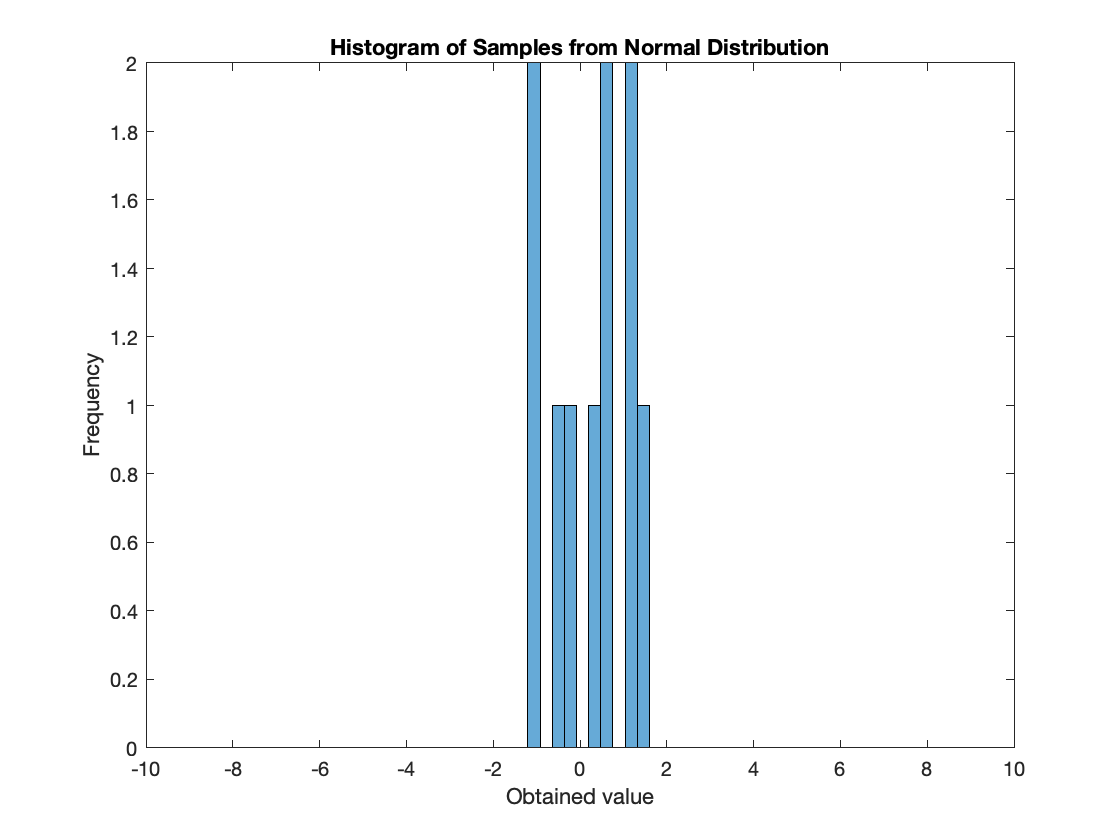

N4 = 10;  % Feel free to change the number of realizations
sample4 = normrnd(mu4,sigma4,1,N4); 

% Plot the Histogram
figure(8);
histogram(sample4,10);
xlabel('Obtained value');
ylabel('Frequency');
xlim([-10 10])
title('Histogram of Samples from Normal Distribution');

**(3.3) **Let's consider the mean value of the distribution $\mathcal{N}(\mu,\sigma^2)$. On the one hand, the theoretical value of the mean can be calculated as follows:


$$\mathbb{E}[X] = \int_{-\infty}^{\infty}xf(x)dx= \mu$$


On the other hand, the practical estimate of the mean is given by the average of the values in the generated sample.

Based on the simulation, let's compute the theoretical value and the practical estimate of the mean. We will compare these two values by computing their absolute difference. Please take different values of $N$ and observe how the absolute difference changes as $N$ varies.

mean_theo4 = mu4

mean_theo4 = 0

mean_prac4 = mean(sample4);
diff4 = abs(mean_theo4 - mean_prac4);
fprintf(['Difference between sample mean and theoretical mean: ',num2str(diff4)])

Difference between sample mean and theoretical mean: 0.24285